%% ============================================================
%  CLASS I EMPENNAGE + CG ENVELOPE TOOL
%  Snorri Gudmundsson Chapter 11, Method 3 baseline
%
%  What this script does:
%  1) Sizes a conventional HT + VT using Snorri's combined Method 3:
%         l_T = sqrt( 2*S*(VHT*cMGC + VVT*b) / (pi*(R1+R2)) )
%  2) Converts tail areas into full trapezoidal planforms
%  3) Plots HT top view and VT side view
%  4) Builds a cargo-aircraft CG loading diagram using N pallets
%  5) Adds handbook/project-style CG limit lines and simple
%     landing-gear-coupled structural isopleths
%
%  IMPORTANT:
%  - This is a clean Class I tool.
%  - It deliberately follows Snorri's Method 3 logic and does not
%    add extra optimisation beyond that.
%  - You must insert your current wing geometry values in the input block.
%
%  Units: SI throughout (m, kg)
%% ============================================================

clear; clc; close all;

%% ============================================================
% 1) USER INPUTS
%% ============================================================

% -----------------------------
% Aircraft / wing geometry
% -----------------------------
ac.L_fus      = 65.0;      % fuselage length [m]

wing.S        = 820.0;     % wing reference area [m^2]  <-- replace with your current value
wing.b        = 72.0;      % wing span [m]              <-- replace
wing.cMGC     = 12.0;      % wing mean geometric chord [m] <-- replace
wing.xLEMAC   = 27;        % x-location of wing MAC leading edge [m] from nose datum <-- replace
wing.sweepLE  = 32.0;      % wing leading-edge sweep [deg]

% Wing quarter-chord reference location
wing.x_qc = wing.xLEMAC + 0.25*wing.cMGC;

% -----------------------------
% Snorri Chapter 11 inputs
% -----------------------------
% Keep VHT and VVT as explicit inputs.
% For a first transport pass you may start with:
% VHT = 1.00 ; VVT = 0.09
tail.VHT      = 1.00;
tail.VVT      = 0.09;

% Snorri-recommended AR ranges are roughly:
% 3 < AR_HT < 5 and 0.9 < AR_VT < 2
tail.AR_HT    = 4.0;
tail.AR_VT    = 1.6;

% Tail taper ratios (chosen as clean first-pass trapezoids)
tail.lambdaHT = 0.35;
tail.lambdaVT = 0.35;

% Tail leading-edge sweep angles [deg]
tail.sweepLE_HT = 32.0;
tail.sweepLE_VT = 38.0;

% Aft fuselage frustum radii for Snorri Method 3 [m]
% R1 = local fuselage radius near wing-quarter-chord station
% R2 = local fuselage radius near tail-root station
aft.R1        = 3.20;
aft.R2        = 1.10;

% -----------------------------
% Mass model for CG/loading
% -----------------------------
mass.OWE      = 255000;    % operating weight empty [kg]
mass.x_OWE    = 31.0;      % OWE CG x-location [m] from nose datum

fuel.m_fuel   = 112000;    % usable fuel mass [kg]
fuel.x_fuel   = wing.x_qc; % put fuel near wing box / wing qc for Class I

% Cargo / pallets
cargo.N       = 12;        % number of pallets in a row
cargo.m_each  = 8000;      % mass per pallet [kg]
cargo.x_start = 9.0;       % start of pallet train [m]
cargo.pitch   = 3.2;       % pallet pitch [m]

% Derived pallet station locations
cargo.x = cargo.x_start + ((1:cargo.N)-0.5)*cargo.pitch;

% Certification / plotting weights
W.MZFW = mass.OWE + cargo.N*cargo.m_each;
W.MTOW = W.MZFW + fuel.m_fuel;
W.MLW  = 0.92*W.MTOW;      % placeholder if you do not yet have a better value

% -----------------------------
% Flight CG limits (project placeholders)
% Replace with your trim / stability outputs later
% -----------------------------
cg.fwd_flight_pctMAC = 15.0;
cg.aft_flight_pctMAC = 35.0;

% -----------------------------
% Landing gear assumptions for ground-based CG limits
% These are Class I assumptions only.
%
% Based on a 500-ton-class benchmark using scaled A380 gear proportions:
% NLG station   ~= 5.1 m
% Equivalent main support station ~= 32.0 m
% -----------------------------
gear.x_nose = 7;        % nose gear ground contact x [m]
gear.x_main = 35.0;     % equivalent main gear ground contact x [m]

% Project notes: at least 2.5% of MTOW must remain on nose wheel at take-off
gear.min_nose_frac_takeoff = 0.025;

% Class I structural assumption for max nose gear reaction
% Snorri landing-gear guidance often uses ~20% nose load at forward limit
gear.max_nose_load = 0.2 * W.MTOW;  % [kg-equivalent load]

% Class I structural assumption for max equivalent main gear reaction
gear.max_main_load = 0.9 * W.MTOW;  % [kg-equivalent load]

%% ============================================================
% 2) SNORRI METHOD 3 : OPTIMUM COMMON TAIL ARM
%    Chapter 11, Eq. (11-28)
%% ============================================================

tail.lT = sqrt( 2*wing.S*(tail.VHT*wing.cMGC + tail.VVT*wing.b) ...
              / (pi*(aft.R1 + aft.R2)) );

% Snorri Eq. (11-20) and (11-23) equivalent area relations
tail.S_HT = tail.VHT * wing.S * wing.cMGC / tail.lT;
tail.S_VT = tail.VVT * wing.S * wing.b    / tail.lT;

% Snorri Eq. (11-21) and (11-24) equivalent span relations
tail.b_HT = sqrt(tail.AR_HT * tail.S_HT);
tail.b_VT = sqrt(tail.AR_VT * tail.S_VT);

%% ============================================================
% 3) CONVERT AREAS TO FULL TRAPEZOIDAL PLANFORMS
%% ============================================================

% -------- Horizontal tail --------
HT = trapezoid_from_S_b_lambda(tail.S_HT, tail.b_HT, tail.lambdaHT);
HT.sweepLE = tail.sweepLE_HT;

HT.cMGC = mean_geom_chord(HT.c_root, HT.lambda);
HT.yMGC = y_mgc(HT.b, HT.lambda);

% Put HT quarter-chord tail.lT behind wing quarter-chord
HT.x_qc = wing.x_qc + tail.lT;

% Snorri-style geometry closure:
% x_qc = x_apex + yMGC*tan(sweepLE) + 0.25*cMGC
HT.x_apex = HT.x_qc - (HT.yMGC*tand(HT.sweepLE) + 0.25*HT.cMGC);

% Planform vertices (full tail)
[HT.x_poly, HT.y_poly] = tail_planform_polygon(HT.x_apex, HT.c_root, ...
                                               HT.c_tip, HT.b, HT.sweepLE);

% -------- Vertical tail --------
VT = trapezoid_from_S_b_lambda(tail.S_VT, tail.b_VT, tail.lambdaVT);
VT.sweepLE = tail.sweepLE_VT;

VT.cMGC = mean_geom_chord(VT.c_root, VT.lambda);
VT.zMGC = y_mgc(VT.b, VT.lambda);   % same formula, but vertical coordinate

VT.x_qc = wing.x_qc + tail.lT;
VT.x_apex = VT.x_qc - (VT.zMGC*tand(VT.sweepLE) + 0.25*VT.cMGC);

[VT.x_poly, VT.z_poly] = fin_planform_polygon(VT.x_apex, VT.c_root, ...
                                              VT.c_tip, VT.b, VT.sweepLE);

%% ============================================================
% 4) PRINT EMPENNAGE RESULTS
%% ============================================================

fprintf('\n================ EMPENNAGE: CLASS I (SNORRI METHOD 3) ================\n');


================ EMPENNAGE: CLASS I (SNORRI METHOD 3) ================


fprintf('Wing reference area S             = %8.3f m^2\n', wing.S);

Wing reference area S             =  820.000 m^2


fprintf('Wing span b                       = %8.3f m\n',   wing.b);

Wing span b                       =   72.000 m


fprintf('Wing mean geometric chord cMGC    = %8.3f m\n',   wing.cMGC);

Wing mean geometric chord cMGC    =   12.000 m


fprintf('Assumed VHT                       = %8.4f\n',     tail.VHT);

Assumed VHT                       =   1.0000


fprintf('Assumed VVT                       = %8.4f\n',     tail.VVT);

Assumed VVT                       =   0.0900


fprintf('Aft fuselage frustum radii R1,R2  = %8.3f , %8.3f m\n', aft.R1, aft.R2);

Aft fuselage frustum radii R1,R2  =    3.200 ,    1.100 m


fprintf('Optimum common tail arm lT        = %8.3f m\n', tail.lT);

Optimum common tail arm lT        =   47.366 m



fprintf('\n---- Horizontal tail ----\n');


---- Horizontal tail ----


fprintf('HT area S_HT                      = %8.3f m^2\n', tail.S_HT);

HT area S_HT                      =  207.745 m^2


fprintf('HT span b_HT                      = %8.3f m\n',   tail.b_HT);

HT span b_HT                      =   28.827 m


fprintf('HT root chord                     = %8.3f m\n',   HT.c_root);

HT root chord                     =   10.677 m


fprintf('HT tip chord                      = %8.3f m\n',   HT.c_tip);

HT tip chord                      =    3.737 m


fprintf('HT MAC                            = %8.3f m\n',   HT.cMGC);

HT MAC                            =    7.764 m


fprintf('HT apex x-location                = %8.3f m\n',   HT.x_apex);

HT apex x-location                =   71.644 m



fprintf('\n---- Vertical tail ----\n');


---- Vertical tail ----


fprintf('VT area S_VT                      = %8.3f m^2\n', tail.S_VT);

VT area S_VT                      =  112.183 m^2


fprintf('VT span/height b_VT               = %8.3f m\n',   tail.b_VT);

VT span/height b_VT               =   13.397 m


fprintf('VT root chord                     = %8.3f m\n',   VT.c_root);

VT root chord                     =   12.405 m


fprintf('VT tip chord                      = %8.3f m\n',   VT.c_tip);

VT tip chord                      =    4.342 m


fprintf('VT MAC                            = %8.3f m\n',   VT.cMGC);

VT MAC                            =    9.020 m


fprintf('VT apex x-location                = %8.3f m\n',   VT.x_apex);

VT apex x-location                =   72.914 m


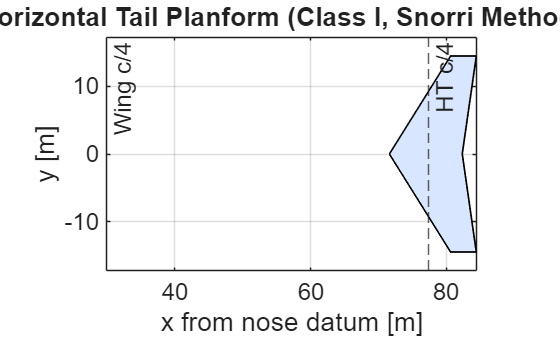


%% ============================================================
% 5) PLOT TAIL PLANFORMS
%% ============================================================

figure('Name','Horizontal Tail Planform');
plot(HT.x_poly, HT.y_poly, 'k-', 'LineWidth', 1.5); hold on;
fill(HT.x_poly, HT.y_poly, [0.85 0.90 1.0], 'EdgeColor', 'k');
axis equal; grid on;
xlabel('x from nose datum [m]', 'FontSize', 18);
ylabel('y [m]', 'FontSize', 18);
title('Horizontal Tail Planform (Class I, Snorri Method 3)', 'FontSize', 22);
xline(wing.x_qc, '--', 'Wing c/4', 'FontSize', 18);
xline(HT.x_qc, '--', 'HT c/4', 'FontSize', 18);
set(gca, 'FontSize', 18);

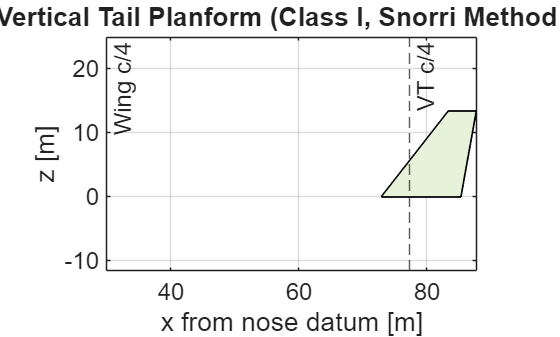


figure('Name','Vertical Tail Planform');
plot(VT.x_poly, VT.z_poly, 'k-', 'LineWidth', 1.5); hold on;
fill(VT.x_poly, VT.z_poly, [0.90 0.95 0.85], 'EdgeColor', 'k');
axis equal; grid on;
xlabel('x from nose datum [m]', 'FontSize', 18);
ylabel('z [m]', 'FontSize', 18);
title('Vertical Tail Planform (Class I, Snorri Method 3)', 'FontSize', 22);
xline(wing.x_qc, '--', 'Wing c/4', 'FontSize', 18);
xline(VT.x_qc, '--', 'VT c/4', 'FontSize', 18);
set(gca, 'FontSize', 18);

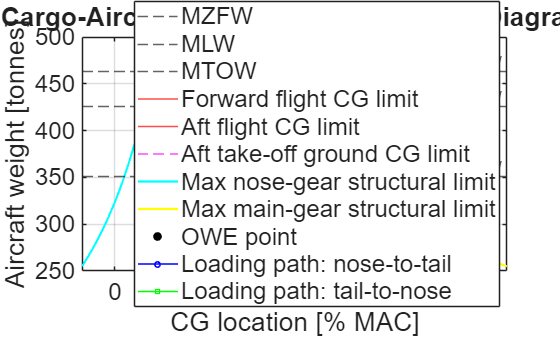


%% ============================================================
% 6) BUILD CARGO LOADING LOCI
%    Nose-to-tail and tail-to-nose pallet loading,
%    then fuel added to MTOW
%% ============================================================

% Forward-critical loading: nose to tail
order_fwd = 1:cargo.N;

% Aft-critical loading: tail to nose
order_aft = cargo.N:-1:1;

[pathF.W, pathF.xcg] = loading_path(mass.OWE, mass.x_OWE, ...
                                    cargo.m_each, cargo.x(order_fwd), ...
                                    fuel.m_fuel, fuel.x_fuel);

[pathA.W, pathA.xcg] = loading_path(mass.OWE, mass.x_OWE, ...
                                    cargo.m_each, cargo.x(order_aft), ...
                                    fuel.m_fuel, fuel.x_fuel);

% Convert to %MAC
pathF.pctMAC = x_to_pctMAC(pathF.xcg, wing.xLEMAC, wing.cMGC);
pathA.pctMAC = x_to_pctMAC(pathA.xcg, wing.xLEMAC, wing.cMGC);

OWE_pctMAC = x_to_pctMAC(mass.x_OWE, wing.xLEMAC, wing.cMGC);

%% ============================================================
% 7) GROUND-REACTION-CONTROLLED CG LIMITS
%% ============================================================

Wgrid = linspace(mass.OWE, W.MTOW, 250);

% Aft TO ground limit from minimum nose-wheel reaction fraction
% Static moment balance:
% Nnose/W = (x_main - xcg)/(x_main - x_nose)
% Require Nnose/W >= f_min
% => xcg <= x_main - f_min*(x_main - x_nose)
x_aft_TO = gear.x_main - gear.min_nose_frac_takeoff*(gear.x_main - gear.x_nose);
pctMAC_aft_TO = x_to_pctMAC(x_aft_TO, wing.xLEMAC, wing.cMGC);

% Forward ground structural limit from max nose gear reaction
% Nnose = W*(x_main - xcg)/(x_main - x_nose) <= Nnose_max
% => xcg >= x_main - Nnose_max*(x_main - x_nose)/W
x_fwd_struct = gear.x_main - gear.max_nose_load*(gear.x_main - gear.x_nose)./Wgrid;
pctMAC_fwd_struct = x_to_pctMAC(x_fwd_struct, wing.xLEMAC, wing.cMGC);

% Rear ground structural limit from max equivalent main gear reaction
% Nmain = W*(xcg - x_nose)/(x_main - x_nose) <= Nmain_max
% => xcg <= x_nose + Nmain_max*(x_main - x_nose)/W
x_aft_struct = gear.x_nose + gear.max_main_load*(gear.x_main - gear.x_nose)./Wgrid;
pctMAC_aft_struct = x_to_pctMAC(x_aft_struct, wing.xLEMAC, wing.cMGC);

%% ============================================================
% 8) CG ENVELOPE PLOT
%% ============================================================

figure('Name','Cargo Aircraft CG Diagram');
hold on; grid on; box on;

% Weight lines
hMZFW = yline(W.MZFW/1000, '--', 'MZFW', 'DisplayName', 'MZFW');
hMLW  = yline(W.MLW/1000 , '--', 'MLW',  'DisplayName', 'MLW');
hMTOW = yline(W.MTOW/1000, '--', 'MTOW', 'DisplayName', 'MTOW');

% Flight envelope limits
hFwdFlight = xline(cg.fwd_flight_pctMAC, 'r-', 'Fwd flight limit', ...
    'LineWidth', 1.2, 'DisplayName', 'Forward flight CG limit');
hAftFlight = xline(cg.aft_flight_pctMAC, 'r-', 'Aft flight limit', ...
    'LineWidth', 1.2, 'DisplayName', 'Aft flight CG limit');

% Aft take-off ground limit (2.5% nose-wheel rule)
hAftTO = xline(pctMAC_aft_TO, 'm--', 'Aft TO ground limit (2.5% nose load)', ...
    'LineWidth', 1.2, 'DisplayName', 'Aft ground CG limit');

% Forward structural isopleth from max nose-gear load
hStruct = plot(pctMAC_fwd_struct, Wgrid/1000, 'c-', 'LineWidth', 1.6, ...
    'DisplayName', 'Max nose gear limit');

% Rear structural isopleth from max main-gear load
hRearStruct = plot(pctMAC_aft_struct, Wgrid/1000, 'y-', 'LineWidth', 1.6, ...
    'DisplayName', 'Max main gear limit');

% OWE point
hOWE = plot(OWE_pctMAC, mass.OWE/1000, 'ko', 'MarkerFaceColor', 'k', ...
    'DisplayName', 'OWE point');

% Loading paths
hPathF = plot(pathF.pctMAC, pathF.W/1000, 'b-o', 'LineWidth', 1.2, 'MarkerSize', 4, ...
    'DisplayName', 'Loading path: nose -> tail');
hPathA = plot(pathA.pctMAC, pathA.W/1000, 'g-s', 'LineWidth', 1.2, 'MarkerSize', 4, ...
    'DisplayName', 'Loading path: tail -> nose');

xlabel('CG location [% MAC]', 'FontSize', 18);
ylabel('Aircraft weight [tonnes]', 'FontSize', 18);
title('Cargo-Aircraft CG Envelope / Loading Diagram', 'FontSize', 22);

legend([hMZFW, hMLW, hMTOW, hFwdFlight, hAftFlight, hAftTO, hStruct, hRearStruct, hOWE, hPathF, hPathA], ...
       {'MZFW', ...
        'MLW', ...
        'MTOW', ...
        'Forward flight CG limit', ...
        'Aft flight CG limit', ...
        'Aft take-off ground CG limit', ...
        'Max nose-gear structural limit', ...
        'Max main-gear structural limit', ...
        'OWE point', ...
        'Loading path: nose-to-tail', ...
        'Loading path: tail-to-nose'}, ...
       'Location','best', 'FontSize', 18);

set(gca, 'FontSize', 18);

text(OWE_pctMAC, mass.OWE/1000, '  OWE', 'VerticalAlignment','bottom');


% Show pallet stations in console
fprintf('\n================ CARGO PALLET STATIONS ================\n');


================ CARGO PALLET STATIONS ================


for i = 1:cargo.N
    fprintf('Pallet %2d : x = %7.3f m\n', i, cargo.x(i));
end

Pallet  1 : x =  10.600 m
Pallet  2 : x =  13.800 m
Pallet  3 : x =  17.000 m
Pallet  4 : x =  20.200 m
Pallet  5 : x =  23.400 m
Pallet  6 : x =  26.600 m
Pallet  7 : x =  29.800 m
Pallet  8 : x =  33.000 m
Pallet  9 : x =  36.200 m
Pallet 10 : x =  39.400 m
Pallet 11 : x =  42.600 m
Pallet 12 : x =  45.800 m



fprintf('\nCG at OWE                      = %7.3f %%MAC\n', OWE_pctMAC);


CG at OWE                      =  33.333 %MAC


fprintf('CG at MTOW (nose->tail path)   = %7.3f %%MAC\n', pathF.pctMAC(end));

CG at MTOW (nose->tail path)   =  26.479 %MAC


fprintf('CG at MTOW (tail->nose path)   = %7.3f %%MAC\n', pathA.pctMAC(end));

CG at MTOW (tail->nose path)   =  26.479 %MAC


fprintf('Aft TO ground limit            = %7.3f %%MAC\n', pctMAC_aft_TO);

Aft TO ground limit            =  60.833 %MAC


%% ============================================================
% 9) SIMPLE GEOMETRY SANITY CHECKS
%% ============================================================

cargo_end = cargo.x_start + cargo.N*cargo.pitch;
if cargo_end > ac.L_fus
    warning('Pallet train extends beyond fuselage length. Reduce N or pitch, or move x_start.');
end

if tail.lT > 0.45*ac.L_fus
    warning('Tail arm is very long relative to fuselage length. Re-check VHT/VVT and R1/R2 assumptions.');
end

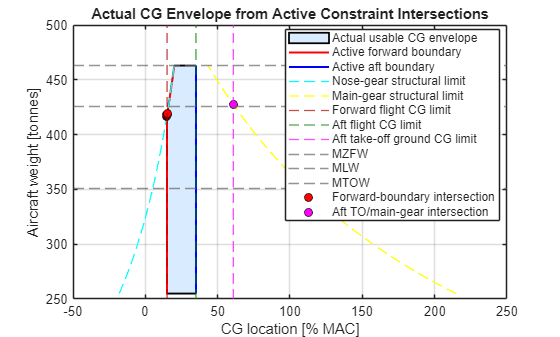


if tail.AR_HT <= 3 || tail.AR_HT >= 5
    warning('HT aspect ratio lies outside Snorri''s preferred first-pass range.');
end

if tail.AR_VT <= 0.9 || tail.AR_VT >= 2.0
    warning('VT aspect ratio lies outside Snorri''s preferred first-pass range.');
end

%% ============================================================
% 8B) ACTUAL CG ENVELOPE PLOT FROM ACTIVE INTERSECTIONS
%% ============================================================

% Convert constant flight/ground vertical limits into vectors over Wgrid
left_flight_vec  = cg.fwd_flight_pctMAC * ones(size(Wgrid));
right_flight_vec = cg.aft_flight_pctMAC * ones(size(Wgrid));
right_TO_vec     = pctMAC_aft_TO       * ones(size(Wgrid));

% Active usable envelope boundaries
env_left  = max(left_flight_vec,  pctMAC_fwd_struct);
env_right = min(right_flight_vec, min(right_TO_vec, pctMAC_aft_struct));

% Valid region mask
valid_env = env_left <= env_right;

% Keep only valid parts
Wenv       = Wgrid(valid_env);
env_left_v = env_left(valid_env);
env_right_v= env_right(valid_env);

% Build polygon for fill
x_env_poly = [env_left_v, fliplr(env_right_v)];
y_env_poly = [Wenv/1000, fliplr(Wenv/1000)];

% ---- Find relevant intersection points numerically ----
tol = 0.25;  % %MAC tolerance for intersection marking

% Forward side intersections
idx_fwd_switch = find(abs(cg.fwd_flight_pctMAC - pctMAC_fwd_struct) < tol);

% Aft side intersections
idx_aft_flight_main = find(abs(cg.aft_flight_pctMAC - pctMAC_aft_struct) < tol);
idx_aft_TO_main     = find(abs(pctMAC_aft_TO - pctMAC_aft_struct) < tol);

% Create new figure
figure('Name','Actual CG Envelope');
hold on; grid on; box on;

% Shade actual envelope
fill(x_env_poly, y_env_poly, [0.85 0.92 1.00], ...
    'EdgeColor', 'k', 'LineWidth', 1.4, ...
    'DisplayName', 'Actual usable CG envelope');

% Plot active boundaries on top
plot(env_left,  Wgrid/1000, 'r-', 'LineWidth', 1.5, ...
    'DisplayName', 'Active forward boundary');
plot(env_right, Wgrid/1000, 'b-', 'LineWidth', 1.5, ...
    'DisplayName', 'Active aft boundary');

% Also show construction limits faintly for reference
plot(pctMAC_fwd_struct, Wgrid/1000, 'c--', 'LineWidth', 1.0, ...
    'DisplayName', 'Nose-gear structural limit');
plot(pctMAC_aft_struct, Wgrid/1000, 'y--', 'LineWidth', 1.0, ...
    'DisplayName', 'Main-gear structural limit');

xline(cg.fwd_flight_pctMAC, 'Color', [0.7 0 0], 'LineStyle', '--', ...
    'LineWidth', 1.0, 'DisplayName', 'Forward flight CG limit');
xline(cg.aft_flight_pctMAC, 'Color', [0 0.5 0], 'LineStyle', '--', ...
    'LineWidth', 1.0, 'DisplayName', 'Aft flight CG limit');
xline(pctMAC_aft_TO, 'm--', 'LineWidth', 1.0, ...
    'DisplayName', 'Aft take-off ground CG limit');

% Weight lines
yline(W.MZFW/1000, '--', 'Color', [0.4 0.4 0.4], 'DisplayName', 'MZFW');
yline(W.MLW /1000, '--', 'Color', [0.4 0.4 0.4], 'DisplayName', 'MLW');
yline(W.MTOW/1000, '--', 'Color', [0.4 0.4 0.4], 'DisplayName', 'MTOW');

% Plot relevant intersection points
if ~isempty(idx_fwd_switch)
    plot(pctMAC_fwd_struct(idx_fwd_switch), Wgrid(idx_fwd_switch)/1000, ...
        'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Forward-boundary intersection');
end

if ~isempty(idx_aft_flight_main)
    plot(pctMAC_aft_struct(idx_aft_flight_main), Wgrid(idx_aft_flight_main)/1000, ...
        'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Aft-boundary intersection');
end

if ~isempty(idx_aft_TO_main)
    plot(pctMAC_aft_struct(idx_aft_TO_main), Wgrid(idx_aft_TO_main)/1000, ...
        'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Aft TO/main-gear intersection');
end

xlabel('CG location [% MAC]');
ylabel('Aircraft weight [tonnes]');
title('Actual CG Envelope from Active Constraint Intersections');

legend('Location','best');


%% ============================================================
% 8C) PRINT INTERSECTION INFO TO CONSOLE
%% ============================================================

fprintf('\n================ ACTIVE ENVELOPE INTERSECTIONS ================\n');


================ ACTIVE ENVELOPE INTERSECTIONS ================



if ~isempty(idx_fwd_switch)
    for k = 1:numel(idx_fwd_switch)
        i = idx_fwd_switch(k);
        fprintf('Forward flight / nose-gear structural intersection:  %7.3f %%MAC at %7.3f t\n', ...
            pctMAC_fwd_struct(i), Wgrid(i)/1000);
    end
else
    fprintf('No forward flight / nose-gear structural intersection found in plotted range.\n');
end

Forward flight / nose-gear structural intersection:   14.755 %MAC at 416.221 t
Forward flight / nose-gear structural intersection:   14.859 %MAC at 417.056 t
Forward flight / nose-gear structural intersection:   14.963 %MAC at 417.892 t
Forward flight / nose-gear structural intersection:   15.066 %MAC at 418.727 t
Forward flight / nose-gear structural intersection:   15.169 %MAC at 419.562 t



if ~isempty(idx_aft_flight_main)
    for k = 1:numel(idx_aft_flight_main)
        i = idx_aft_flight_main(k);
        fprintf('Aft flight / main-gear structural intersection:      %7.3f %%MAC at %7.3f t\n', ...
            pctMAC_aft_struct(i), Wgrid(i)/1000);
    end
else
    fprintf('No aft flight / main-gear structural intersection found in plotted range.\n');
end

No aft flight / main-gear structural intersection found in plotted range.



if ~isempty(idx_aft_TO_main)
    for k = 1:numel(idx_aft_TO_main)
        i = idx_aft_TO_main(k);
        fprintf('Aft TO / main-gear structural intersection:          %7.3f %%MAC at %7.3f t\n', ...
            pctMAC_aft_struct(i), Wgrid(i)/1000);
    end
else
    fprintf('No aft TO / main-gear structural intersection found in plotted range.\n');
end

Aft TO / main-gear structural intersection:           60.995 %MAC at 427.080 t



%% ============================================================
% LOCAL FUNCTIONS
%% ============================================================

function T = trapezoid_from_S_b_lambda(S, b, lambda)
    T.S = S;
    T.b = b;
    T.lambda = lambda;
    T.c_root = 2*S/(b*(1+lambda));
    T.c_tip  = lambda*T.c_root;
end

function cbar = mean_geom_chord(c_root, lambda)
    cbar = (2/3)*c_root*((1 + lambda + lambda^2)/(1 + lambda));
end

function ybar = y_mgc(b, lambda)
    ybar = (b/6)*((1 + 2*lambda)/(1 + lambda));
end

function [xpoly, ypoly] = tail_planform_polygon(x_apex, c_root, c_tip, b, sweepLE_deg)
    ysemi = b/2;
    xLE_tip = x_apex + ysemi*tand(sweepLE_deg);

    % Full polygon, clockwise
    xpoly = [ ...
        x_apex, ...
        xLE_tip, ...
        xLE_tip + c_tip, ...
        x_apex + c_root, ...
        x_apex + c_root, ...
        xLE_tip + c_tip, ...
        xLE_tip, ...
        x_apex, ...
        x_apex ];

    ypoly = [ ...
         0, ...
         ysemi, ...
         ysemi, ...
         0, ...
         0, ...
        -ysemi, ...
        -ysemi, ...
         0, ...
         0 ];
end

function [xpoly, zpoly] = fin_planform_polygon(x_apex, c_root, c_tip, h, sweepLE_deg)
    xLE_tip = x_apex + h*tand(sweepLE_deg);

    xpoly = [x_apex, xLE_tip, xLE_tip + c_tip, x_apex + c_root, x_apex];
    zpoly = [0,     h,       h,               0,              0];
end

function [Wvec, xcgvec] = loading_path(OWE, xOWE, m_each, x_payload, m_fuel, x_fuel)

    W = OWE;
    M = OWE*xOWE;

    Wvec = W;
    xcgvec = M/W;

    % Add payload in sequence
    for i = 1:numel(x_payload)
        W = W + m_each;
        M = M + m_each*x_payload(i);
        Wvec(end+1,1)   = W;      %#ok<AGROW>
        xcgvec(end+1,1) = M/W;    %#ok<AGROW>
    end

    % Add fuel last
    W = W + m_fuel;
    M = M + m_fuel*x_fuel;
    Wvec(end+1,1)   = W;
    xcgvec(end+1,1) = M/W;
end

function pct = x_to_pctMAC(x, xLEMAC, cMGC)
    pct = 100*(x - xLEMAC)/cMGC;
end